clc
clear

imgPath = 'imgs/landscape.jpg';
% imgPath = 'imgs/tivoli.jpg';
% imgPath = 'imgs/tivoli2.jpeg';
% imgPath = 'imgs/mountain_low_res.png';
% imgPath = 'imgs/mountains_2.jpg';
% imgPath = 'imgs/landscape_mountain.jpg';


## Image preprocessing

minW = 600;        % Min input width (px)
maxW = 3000;       % Max input width (px)
Wout = 1200;       % Output width (px)

img = im2double(imread(imgPath));
[height, width] = size(img);
fprintf("Original size: %d x %d \n", width, height)

Original size: 1650 x 367 


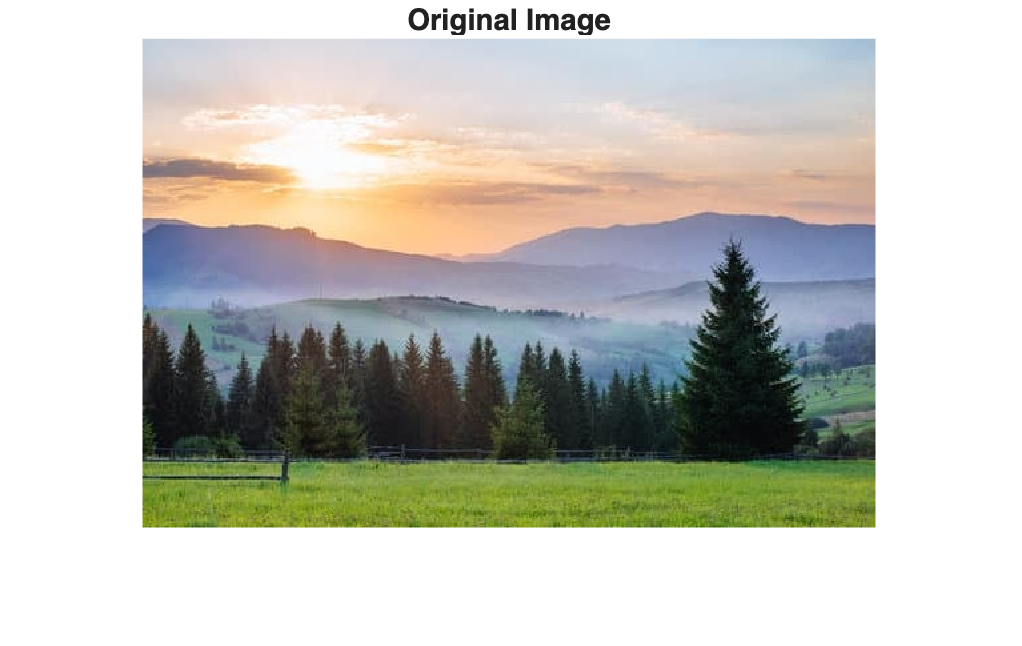

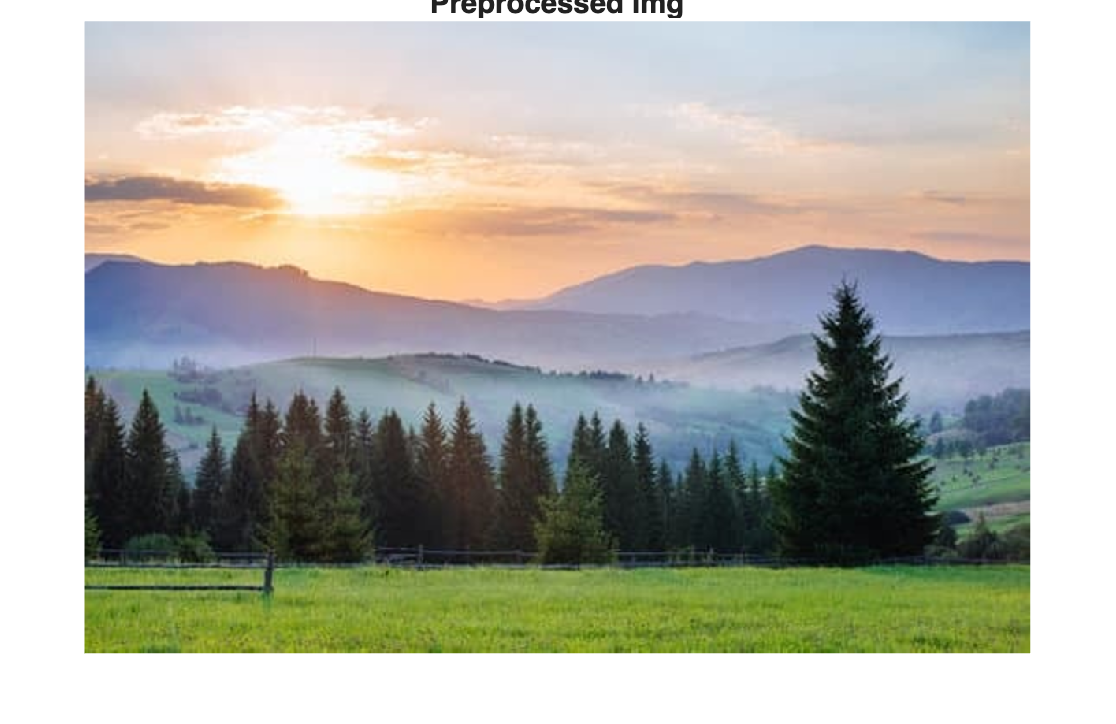

processedImg = preprocessImage(img, minW, maxW, Wout);

Ilab = rgb2lab(processedImg);

## Color palette generation & palette optimization

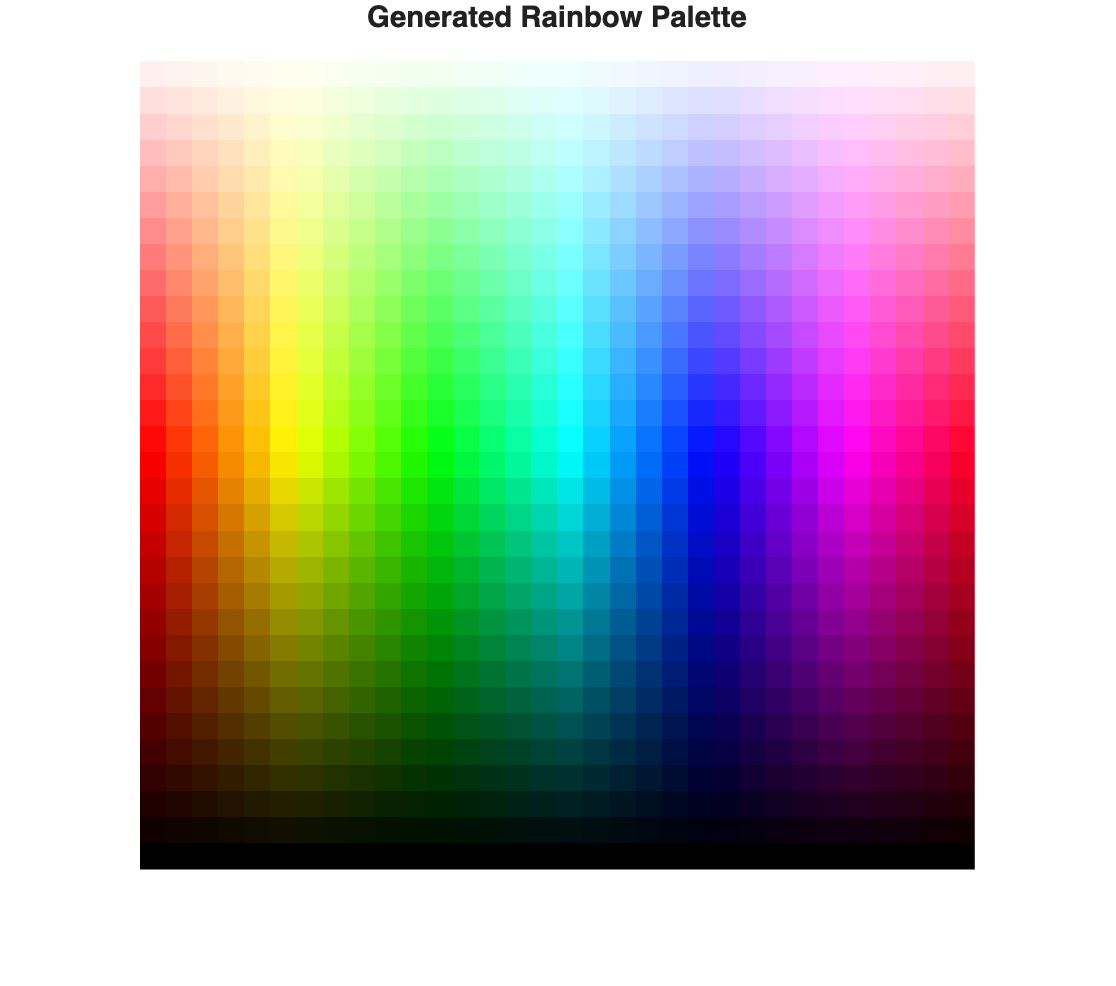

numColors= 32;              % Number of base colors
numShades = 32;             % Number of shades of the base colors
numGlobalColors = 256;      % Number of global colors
numColorsReduced = 128;     % Number of colors that the final comparisons will use
coverage_ratio = 1;

% Generate rainbow palette
[fullPaletteLab, paletteImage] = make_rainbow_palette(numColors, numShades);

figure;
imshow(imresize(paletteImage, 20, 'nearest')); 
title('Generated Rainbow Palette');

fprintf('Generated Palette (%d colors) \n', numColors * numShades);

Generated Palette (1024 colors) 


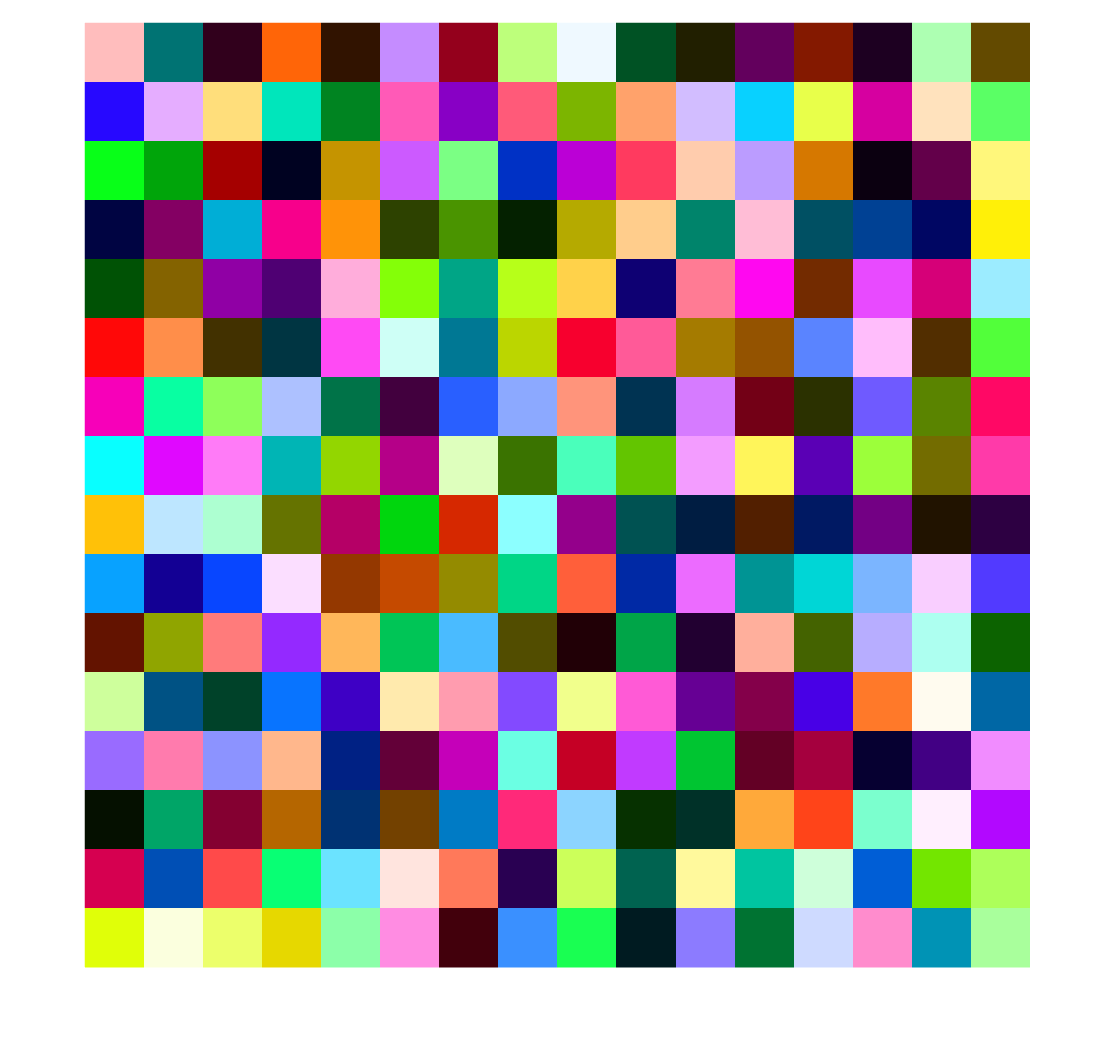


% Optimize it to 256 global colors


[globalLab, globalSwatch] = optimize_palette_global(fullPaletteLab, numGlobalColors);

figure;
imshow(imresize(globalSwatch, 10, "nearest"));
title(sprintf("%d Global colors \n", numGlobalColors));

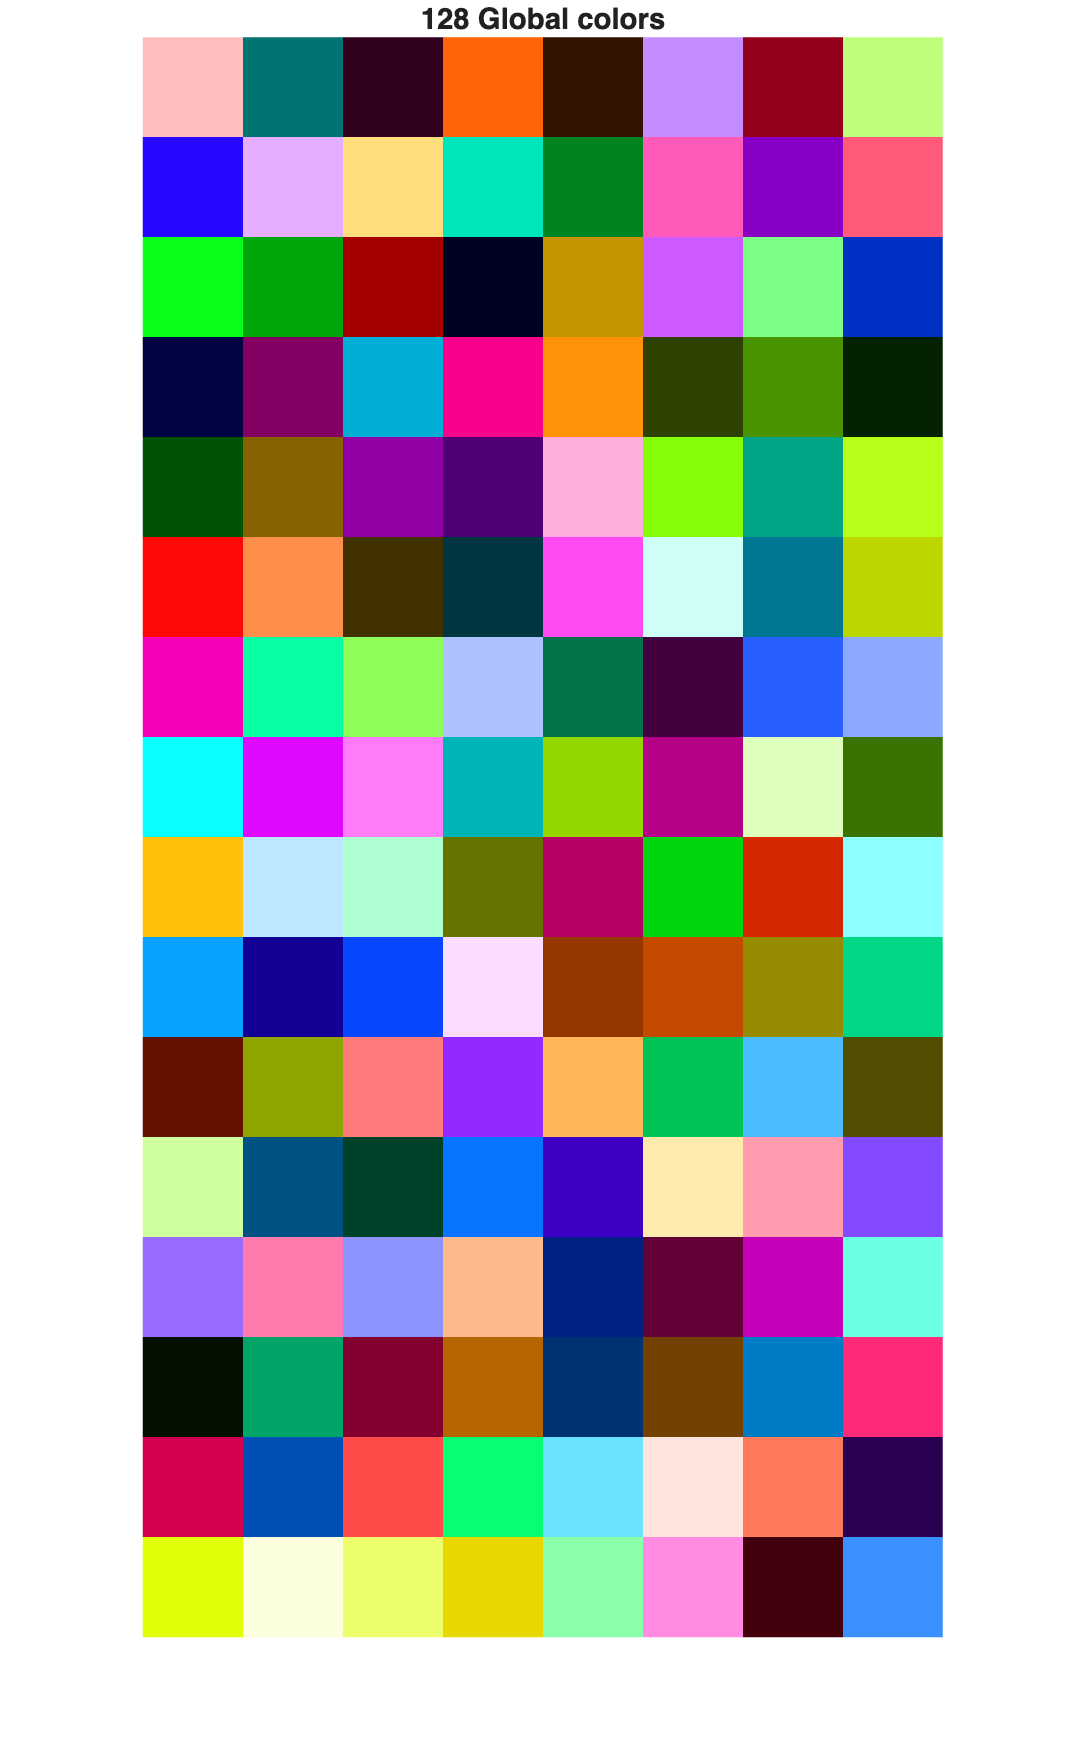


[globalReduced, globalReducedSwatch] = reduce_palette_global(globalLab, numColorsReduced);

figure;
imshow(imresize(globalReducedSwatch, 10, "nearest"));
title(sprintf("%d Global colors", numColorsReduced));

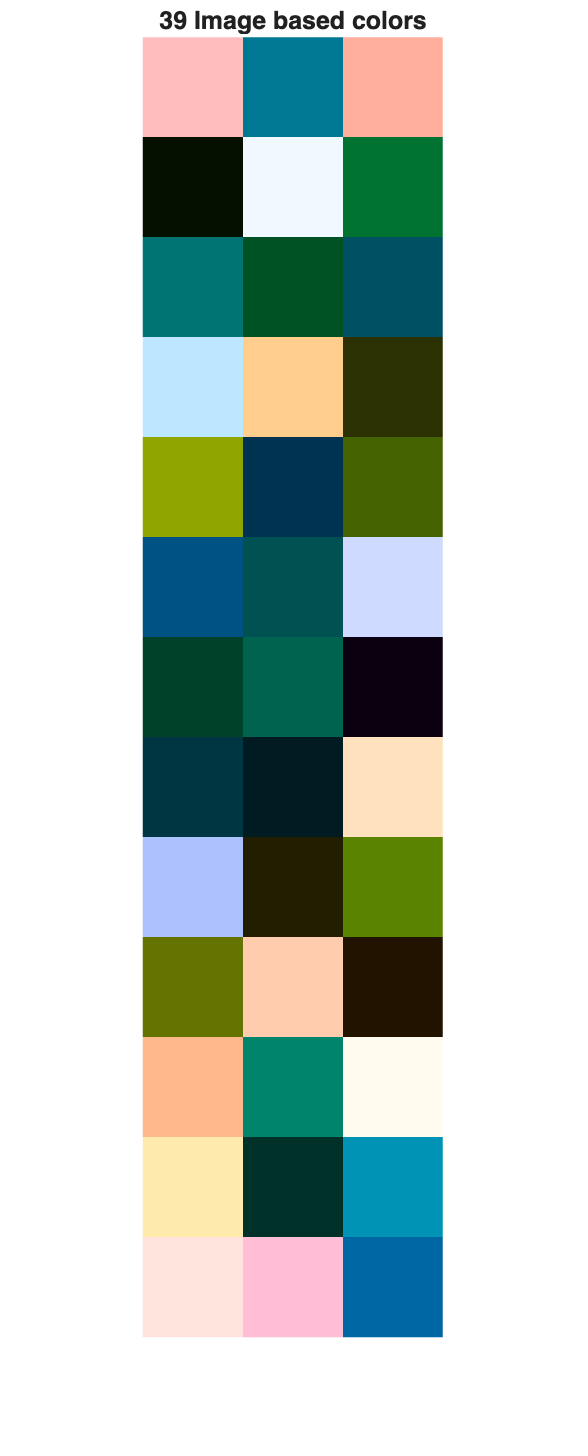


[imageReducedLab, imageReducedSwatch] = optimize_palette_image(Ilab, globalLab, numColorsReduced, coverage_ratio);

figure;
imshow(imresize(imageReducedSwatch, 10, "nearest"));
title(sprintf("%d Image based colors", size(imageReducedLab, 1)));

## Image reconstruction

maxSize = 32;              % Largest triangle size (px)
minSize = 2;               % Smallest triangle size (px)
detailThreshold = 10;      % How much brightness variation triggers a subdivision

[mosaicGlob] = reproduce_adaptive_triangle(Ilab, globalLab, maxSize, minSize, detailThreshold, coverage_ratio);
[mosaicGlobOptimized] = reproduce_adaptive_triangle(Ilab, globalReduced, maxSize, minSize, detailThreshold, coverage_ratio);
[mosaicImageOptimized] = reproduce_adaptive_triangle(Ilab, imageReducedLab, maxSize, minSize, detailThreshold, coverage_ratio);

fprintf("Largest triangles: %d and smallest triangles: %d", maxSize, minSize)

Largest triangles: 32 and smallest triangles: 2

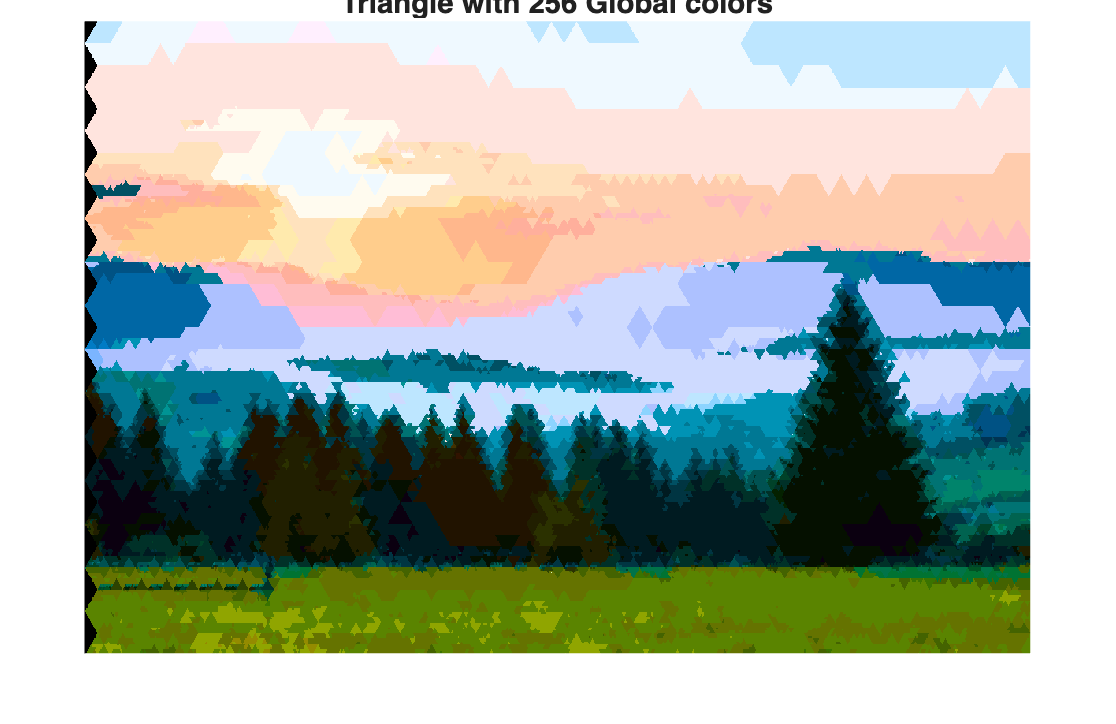


% Global colors
figure;
imshow(mosaicGlob);
axis image off;
title('Triangle with 256 Global colors');


% Evaluation
[ssim_score_glob, psnr_score_glob, scielab_score_glob] = evaluate_quality(processedImg, mosaicGlob);

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


fprintf('--- Quality Metrics ---\n');

--- Quality Metrics ---


fprintf('SSIM:      %.4f (Higher is better)\n', ssim_score_glob);

SSIM:      0.6581 (Higher is better)


fprintf('PSNR:      %.2f dB (Higher is better)\n', psnr_score_glob);

PSNR:      15.72 dB (Higher is better)


fprintf('S-CIELAB:  %.4f (Lower is better)\n', scielab_score_glob);

S-CIELAB:  62.4065 (Lower is better)


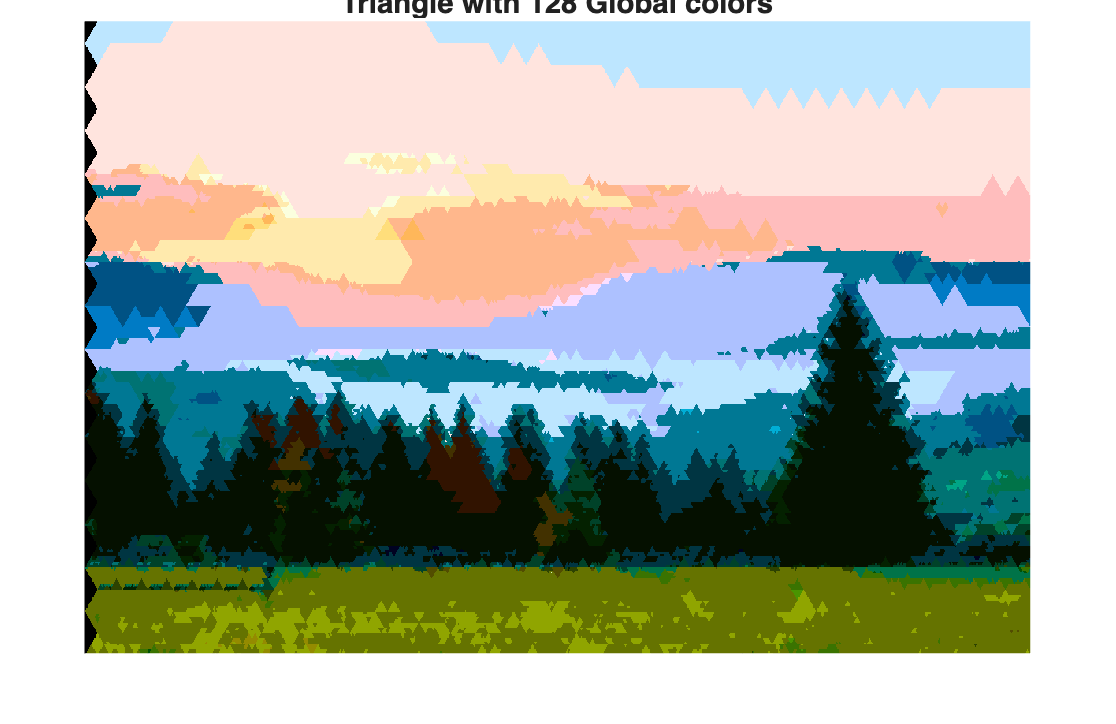


% Optimized Global colors
figure;
imshow(mosaicGlobOptimized);
axis image off;
title('Triangle with 128 Global colors');


% Evaluation
[ssim_score_globOpt, psnr_score_globOpt, scielab_score_globOpt] = evaluate_quality(processedImg, mosaicGlobOptimized);

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


fprintf('--- Quality Metrics ---\n');

--- Quality Metrics ---


fprintf('SSIM:      %.4f (Higher is better)\n', psnr_score_globOpt);

SSIM:      15.7375 (Higher is better)


fprintf('PSNR:      %.2f dB (Higher is better)\n', ssim_score_globOpt);

PSNR:      0.58 dB (Higher is better)


fprintf('S-CIELAB:  %.4f (Lower is better)\n', scielab_score_globOpt);

S-CIELAB:  74.2136 (Lower is better)


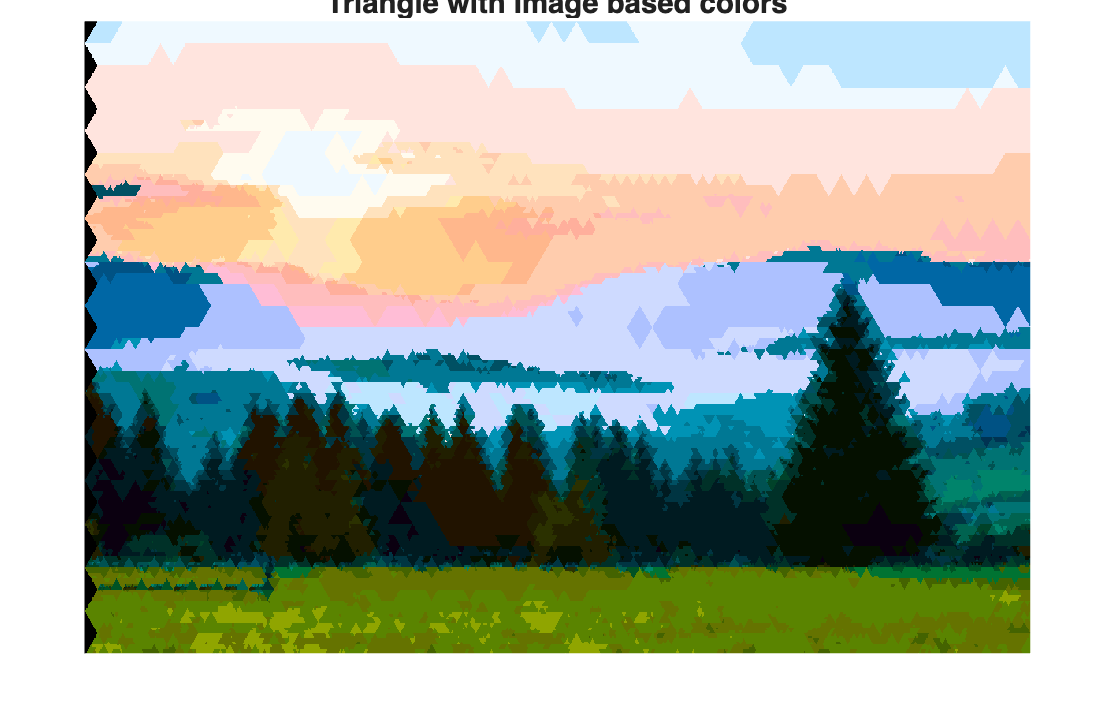


% Optimized Image colors
figure;
imshow(mosaicImageOptimized);
axis image off;
title('Triangle with Image based colors');


% Evaluation
[ssim_score_imgOpt, psnr_score_imgOpt, scielab_score_imgOpt] = evaluate_quality(processedImg, mosaicImageOptimized);

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


fprintf('--- Quality Metrics ---\n');

--- Quality Metrics ---


fprintf('SSIM:      %.4f (Higher is better)\n', ssim_score_imgOpt);

SSIM:      0.6576 (Higher is better)


fprintf('PSNR:      %.2f dB (Higher is better)\n', psnr_score_imgOpt);

PSNR:      15.71 dB (Higher is better)


fprintf('S-CIELAB:  %.4f (Lower is better)\n', scielab_score_imgOpt);

S-CIELAB:  62.6855 (Lower is better)
